clear all
% 100 logarthmically spaced points between 10^0 and 10^-20
h = logspace(-20,0,100);

x0 = pi/4;
derivative= dydx(x0);

dydx_approx = (sin(x0+h)-sin(x0-h))./(2*h)   %IMPLEMENT equation (2.4) here 

dydx_approx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.8054    0.5058    0.9530    0.7980    0.6264    0.7082    0.6918    0.7138    0.7212    0.7222    0.7073    0.7097    0.7065    0.7084    0.7068    0.7075    0.7071    0.7071    0.7070    0.7070    0.7072    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071


abserr = abs(derivative - dydx_approx);

truncation_error = cos(x0)*h.*h/6   %Compute truncation_error

truncation_error =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


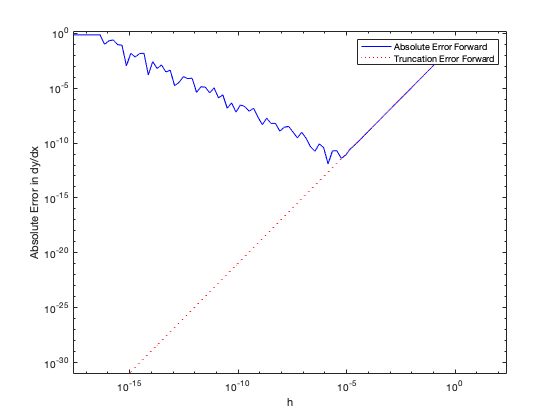



clf
figure(1)
loglog(h,abserr,'b')
hold on
figure(1)
loglog(h(25:100),truncation_error(25:100),'r:')

xlabel('h')
ylabel('Absolute Error in dy/dx')

legend('Absolute Error Forward','Truncation Error Forward')


function der = dydx(x)
%this fucntion computes the derivative of sinx(x)
% YOUR CODE GOES HERE.
der = cos(x);
end